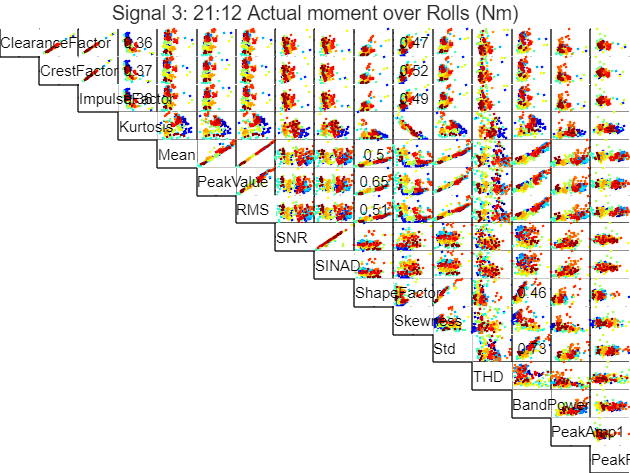

Features = DFD_FeatureTable_TimeDomain;
FeatureNames = FeatureNames_Combined;
lowerR2 = 0.3;
upperR2 = 0.8;
signalNum = 3;
R2 = fnPlotFeatureVsFeature_Array(featureArray, lowerR2, upperR2, signalNum, FeatureNames, sensorNames);

disp(num2str(R2, '%.2f  '));

0.00  0.99  1.00  0.36  0.00  0.04  0.00  0.03  0.01  0.25  0.47  0.08  0.02  0.00  0.00  0.00
0.00  0.00  0.99  0.37  0.01  0.01  0.01  0.03  0.01  0.16  0.52  0.03  0.03  0.01  0.01  0.00
0.00  0.00  0.00  0.36  0.00  0.03  0.00  0.03  0.01  0.21  0.49  0.06  0.03  0.00  0.00  0.00
0.00  0.00  0.00  0.00  0.10  0.03  0.09  0.06  0.02  0.05  0.87  0.00  0.06  0.12  0.02  0.00
0.00  0.00  0.00  0.00  0.00  0.95  1.00  0.02  0.01  0.50  0.26  0.82  0.07  0.86  0.25  0.00
0.00  0.00  0.00  0.00  0.00  0.00  0.95  0.01  0.01  0.65  0.12  0.91  0.05  0.83  0.24  0.00
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.02  0.01  0.51  0.25  0.83  0.06  0.87  0.25  0.00
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.88  0.00  0.06  0.00  0.03  0.01  0.09  0.00
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.02  0.00  0.12  0.00  0.11  0.00
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.87  0.00  0.46  0.20  0.00
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.

selectedFeature = 1;
[selectedFeatureArray, selectedFeatureData, numOfSelectedFeatures] = fnSelectFeatures(signalNum, selectedFeature, featureArray, R2, upperR2, lowerR2);

     1     4    11



disp(selectedFeatureArray);

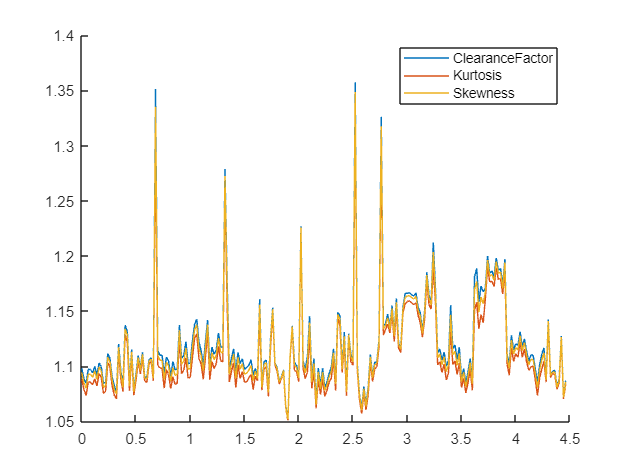

n = size(selectedFeatureData{1}, 1); 
t = ( 0 : 1/fs : (n / fs) - 1/fs)';
figure(); hold on;
leg = {numOfSelectedFeatures};
for signalIndex = 1:numOfSelectedFeatures
    plot(t, selectedFeatureData{signalIndex});
    txtTemp = char(FeatureNames(selectedFeatureArray(signalIndex)));
    leg{signalIndex} = char(txtTemp);
end
legend(leg);

disp(selectedFeatureArray);

     1     4    11



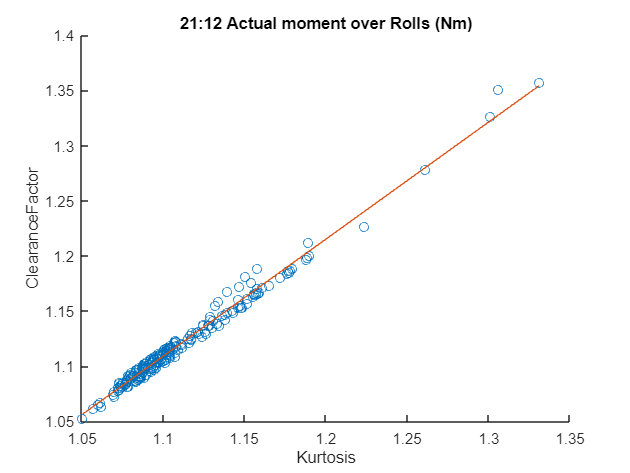

FIT = 88.17

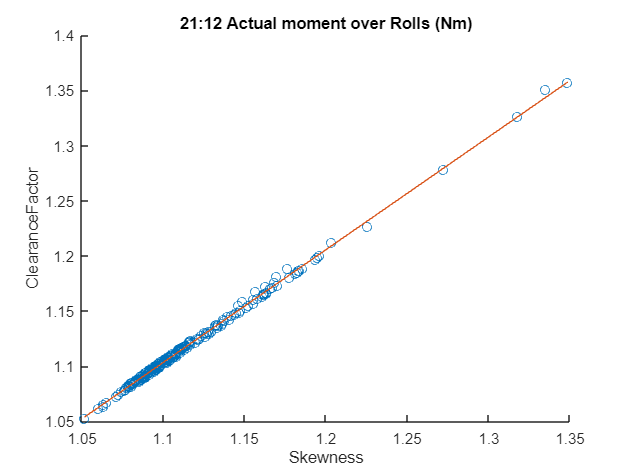

FIT = 95.56

for index = 1 : numOfSelectedFeatures
    if index ~= selectedFeature
        fnPlotModel(selectedFeatureData{selectedFeature}, selectedFeatureData{index}, sensorNames(signalNum), FeatureNames(selectedFeatureArray(selectedFeature)), FeatureNames(selectedFeatureArray(index)));
    end
end

1 2 3

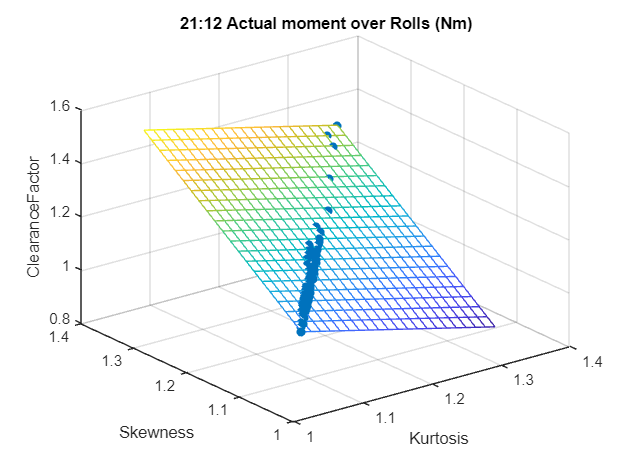

FIT = 99.581057

for index1 = 2 : numOfSelectedFeatures
    for index2 = index1+1 : numOfSelectedFeatures
        fprintf("%i %i %i", 1, index1, index2);
        Y_est = fnPlotModel3D( ...
            selectedFeatureData{1}, ...
            selectedFeatureData{index1}, ...
            selectedFeatureData{index2}, ...
            sensorNames(signalNum), ...
            FeatureNames(selectedFeatureArray(1)), ...
            FeatureNames(selectedFeatureArray(index1)), ...
            FeatureNames(selectedFeatureArray(index2)));
    end
end

selectedFeature = 10;
[selectedFeatureArray, selectedFeatureData, numOfSelectedFeatures] = fnSelectFeatures(signalNum, selectedFeature, featureArray, R2, upperR2, lowerR2);

     5     6     7    10    14



disp(selectedFeatureArray);

selectedFeature = 11;
[selectedFeatureArray, selectedFeatureData, numOfSelectedFeatures] = fnSelectFeatures(signalNum, selectedFeature, featureArray, R2, upperR2, lowerR2);

     1     2     3    11



disp(selectedFeatureArray);

selectedFeature = 14;
[selectedFeatureArray, selectedFeatureData, numOfSelectedFeatures] = fnSelectFeatures(signalNum, selectedFeature, featureArray, R2, upperR2, lowerR2);

    10    12    14



disp(selectedFeatureArray);